Ejercicios raíces

Tanque esférico de radio R

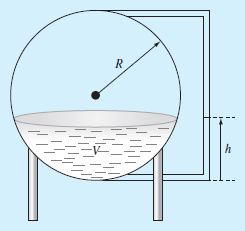


$$V=\pi h^3 \left(\frac{3R-h}{3}\right)$$


Queremos encnontrar un h tal$V=V_d$

Vd = 30;
R = 3;

f=@(h) pi*h.^2*(3*R-h)/3-30;
fplot(f,[0 3])

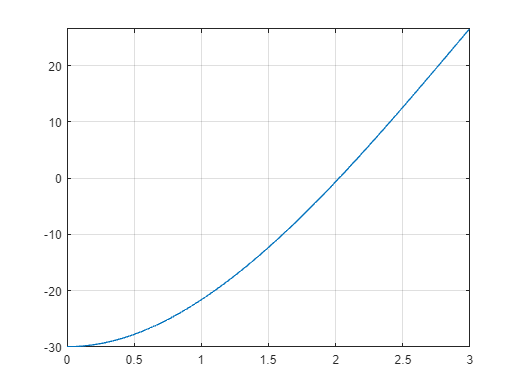

grid on


[R1(1), I1(1)] = R4_rfNewton(f,2);
[R1(2), I1(2)] = R3_Secante(f,1.8,2.2)

R1 =     2.0269    2.0269


I1 =      4     6



f(R1(1))

ans = 3.5527e-15

Bungee jumper 

Determina la masa máxima que puede tener un saltador si, por motivos de seguridad, la velocidad no puede exceder de 33m/s a los 4s. 


$$v=\sqrt{g\frac{m}{c_d }}\tanh \left(\sqrt{g\frac{c_d }{m}t}\right)$$


g = 9.81;
cd = 0.25;
vM = 33;
t = 4;

f=@(m) sqrt(g*m/cd)*tanh(sqrt(g*cd/m)*t)-33

f = function_handle with value:
    @(m)sqrt(g*m/cd)*tanh(sqrt(g*cd/m)*t)-33


fplot(f,[50 100])

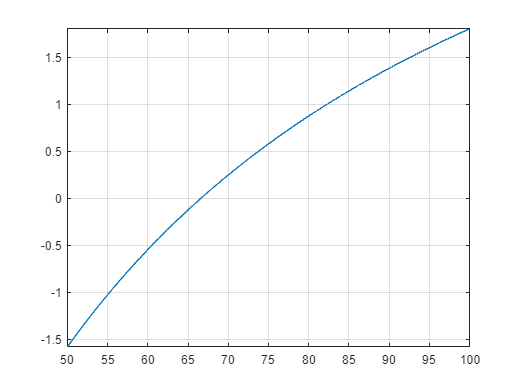

grid on


[R2(1), I2(1)] = R4_rfNewton(f,70);
[R2(2), I2(2)] = R3_Secante(f,60,80)

R2 =    66.6000   66.6000


I2 =      5     7



f(R2(1))

ans = 0

Principio de Arquímedes y una esfera de radio r

De acuerdo con el principio de Arquímedes, la fuerza de flotación es igual al peso del fluido desplazado por la porción sumergida de un objeto. Para la esfera de corcho ilustrada en la siguiente figura, usa el método de bisección para determinar la altura h de la porción que queda encima del agua. Utiliza los siguientes valores para tu cálculo: r = 1m, densidad de la esfera ρe = 200kg/m3 y densidad del agua ρa= 1000kg/m3. Observa que el volumen de la porción de la esfera por encima del agua se puede calcular mediante


$$V=\frac{\pi h^2 }{3}\left(3r-h\right)$$


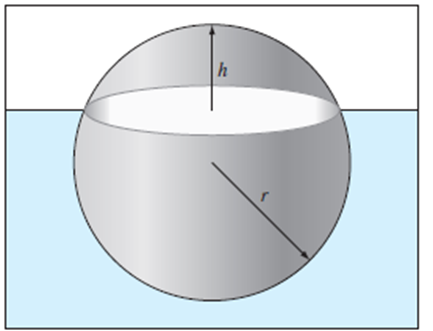

Para estar en equilibrio, la fuerza de flotación (que depende de h) debe ser igual al peso total de la esfera. Recuerda que F=mg y m=ρV. Por lo tanto, F = ρVg.

¿Peso de la esfera? ¿Volumen sumergido (desplazado)? ¿Fuerza de flotación? En equilibrio la fuerza total es cero. 

r = 1;
pe = 200;
pa = 1000;
g = 9.81;

%Fuerza de flotación = fuerza del fluido desplazado 
% = volumen esfera sumergida * pa
%Fuerza de la esfera hacia abajo: F=pVg
f=@(h) pe*g*(4/3*pi*r^3) - (4/3*pi*r^3 - pi*h.^2*(3*r-h)./3)*pa*g

f = function_handle with value:
    @(h)pe*g*(4/3*pi*r^3)-(4/3*pi*r^3-pi*h.^2*(3*r-h)./3)*pa*g


        %Esta parte es el peso de la esfera     y esta es el del agua desp
fplot(f,[0 3])

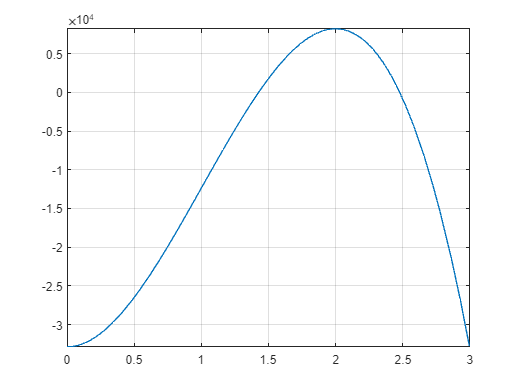

grid on


[R3(1), I3(1)] = R4_rfNewton(f,1);
[R3(2), I3(2)] = R3_Secante(f,1,1.5)

R3 =     1.4257    1.4257


I3 =      6     7



PesoEsfera = pe*(4/3*pi*r^3)

PesoEsfera = 837.7580

VolumenDesplazado = 4/3*pi*r^3 - pi.*R3(1).^2*(3*r-R3(1))/3

VolumenDesplazado = 0.8378


FuerzaFlotacion = pe*(4/3*pi*r^3)*g

FuerzaFlotacion = 8.2184e+03

FuerzaFlotacion = (4/3*pi*r^3 - pi.*R3(2).^2*(3*r-R3(2))/3)*pa*g

FuerzaFlotacion = 8.2184e+03

.